Holtido

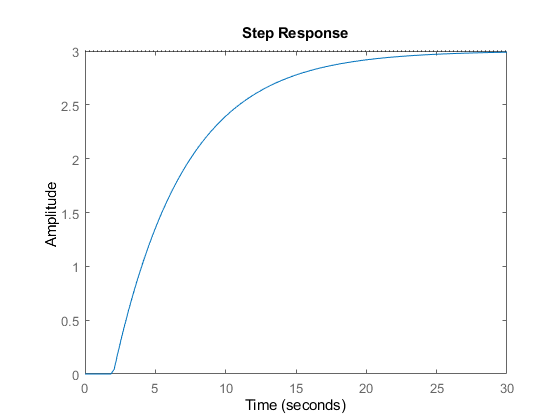

A=3; T1=5; Th=2;
Wp=tf(3, [T1 1], 'OutputDelay', Th);
step(Wp);

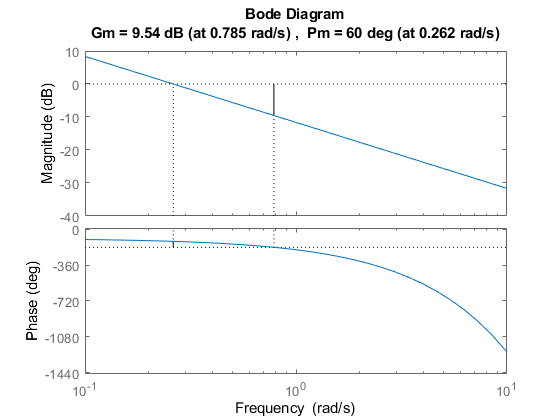


Ap=5*pi/36; Ti=T1; wc=pi/12;
Wc=tf(Ap/Ti*[Ti 1],[1 0]);
Wo= Wc*Wp;
margin(Wo);

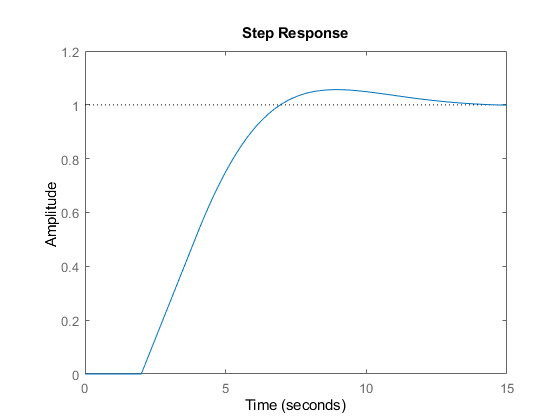


Wcl=feedback(Wo, 1);
step(Wcl);

clear;clc;
megold=fsolve('myPID',[13/4,1,1]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


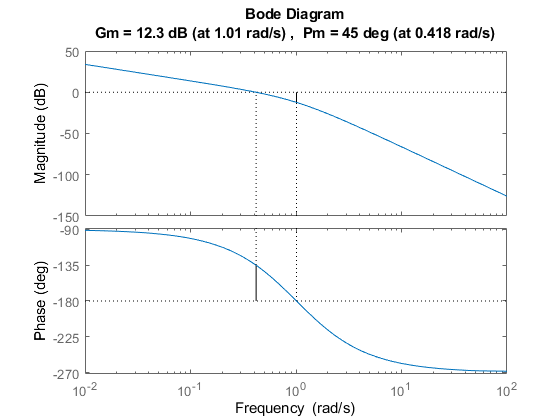

Ap=megold(1); Tc= megold(2);
Ti=14-Tc; Td = 40/(14-Tc)-Tc;
Wc=tf((Ap/Ti)*[Ti*(Tc+Td) Ti+Tc 1], [Tc 1 0]);
Wp= tf(2, conv([10 1], conv([4 1],[1 1])));
Wo=Wc*Wp;
margin(Wo);

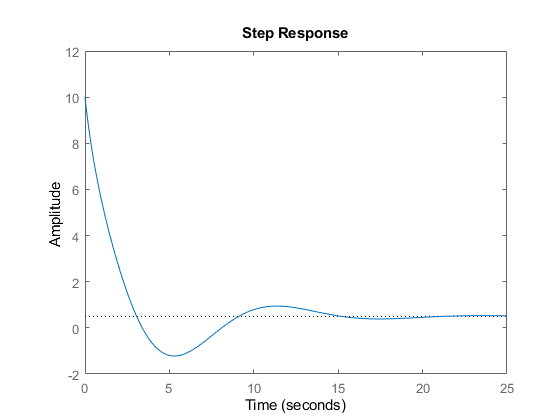

Wcl_ur=feedback(Wc, Wp, -1);
step(Wcl_ur);

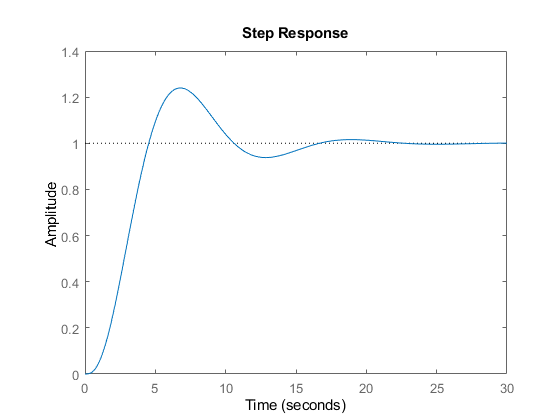

Wcl=feedback(Wc*Wp,1);
step(Wcl);

[Gm,Pm,Wcg,wc] = margin(Wo);

Ts=pi/18/wc

Ts = 0.4172

Dc=c2d(Wc, Ts,'zoh')

Dc =
 
  10 z^2 - 18.79 z + 8.827
  ------------------------
   z^2 - 1.653 z + 0.6534
 
Sample time: 0.4172 seconds
Discrete-time transfer function.



Dp=c2d(Wp,Ts,'zoh')

Dp =
 
  0.000527 z^2 + 0.001836 z + 0.0003977
  -------------------------------------
    z^3 - 2.519 z^2 + 2.09 z - 0.5694
 
Sample time: 0.4172 seconds
Discrete-time transfer function.



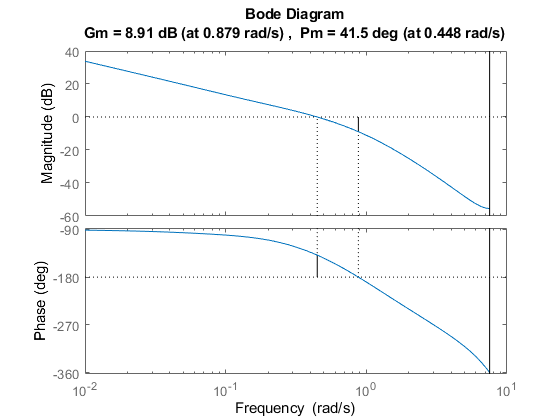

Do=Dc*Dp;
margin(Do);

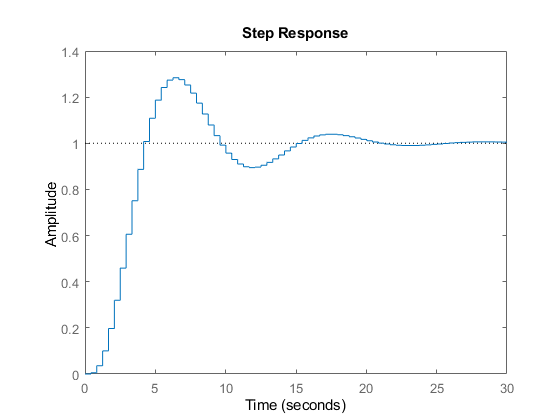

Dcl=feedback(Do, 1);
step(Dcl);